## MEGA PLOT!!!

**Purpose: **Show deterministic bifurcation that occours by show casing a few DE's & their respective solutions. 

**Methods: **ode23 & fplot

**Run Time**: Seconds

clear;

%ODE Solutions
[t1,y1] = ode23(@DE1,[0 4000],.3);
[t2,y2] = ode23(@DE2,[0 4000],.3);
[t3,y3] = ode23(@DE3,[0 4000],.3);

%Make a Tiled Layour
tiledlayout(2,3);

%Plot First DE
nexttile;
fplot(@fDE1,[0 1.4]);

yline(0);
xline(.9807,'--');
hold on;
scatter(0,0,'red','filled');
hold on;
scatter(1.3487,0,'red','filled');
ylabel("Rate of Change");
xlabel("Population Density");
xlim([-.03 1.4]);
ylim([-.002 .009]);

%Plot Second DE
nexttile;
fplot(@fDE2,[0 1.4]);

yline(0);
xline(.9798,'--');
hold on;
scatter(0,0,'red','filled');
hold on;
scatter(1.2865,0,'red','filled');
patch([.5642,.5642],[-.0005,.0006],'r');
ylabel("Rate of Change");
xlabel("Population Density");
xlim([-.03 1.4]);
ylim([-.002 .009]);

%Plot Third DE
nexttile;
fplot(@fDE3,[0 1.4]);

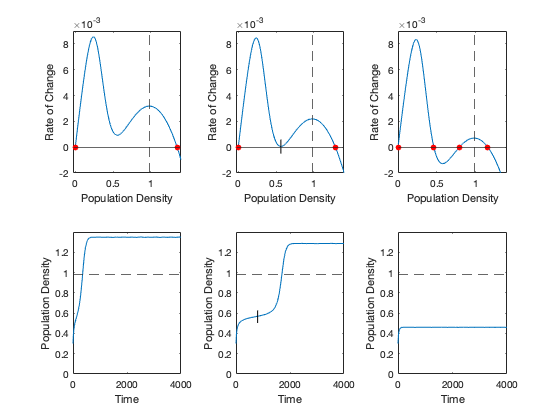

yline(0);
xline(.9782,'--');
hold on;
scatter(0,0,'red',"filled");
hold on;
scatter(.4606,0,'red','filled');
hold on;
scatter(.7881,0,'red','filled');
hold on;
scatter(1.1542,0,'red','filled');
ylabel("Rate of Change");
xlabel("Population Density");
xlim([0 1.4]);
ylim([-.002 .009]);

%Plot First Solution
nexttile;
plot(t1,y1);
yline(.9807,'--')
ylabel("Population Density");
xlabel("Time");
ylim([0 1.4]);

%Plot Second Solution
nexttile;
plot(t2,y2);
yline(.9798,'--');
ylabel("Population Density");
xlabel("Time");
ylim([0 1.4]);
patch([800,800],[.503,.627],'r');

%Plot 3rd Solution
nexttile;
plot(t3,y3);
yline(.9787,'--');
ylabel("Population Density");
xlabel("Time");
ylim([0 1.4]);

function f = fDE1(x)

%Parameters
r = .05;
K = 2;
a = .022;
h = .38;
q = 5;

f = r .* x .* (1-(x/K)) - (a.*x.^(q))/(x.^(q) + h.^(q));

end

function f = DE1(t,x)

%Parameters
r = .05;
K = 2;
a = .022;
h = .38;
q = 5;

f = r * x * (1-(x/K)) - (a*x^(q))/(x^(q) + h^(q));

end

function f = fDE2(x)

%Parameters
r = .05;
K = 2;
a = .023;
h = .38;
q = 5;

f = r .* x .* (1-(x/K)) - (a.*x.^(q))/(x.^(q) + h.^(q));

end

function f = DE2(t,x)

%Parameters
r = .05;
K = 2;
a = .023;
h = .38;
q = 5;

f = r * x * (1-(x/K)) - (a*x^(q))/(x^(q) + h^(q));

end

function f = fDE3(x)

%Parameters
r = .05;
K = 2;
a = .0245;
h = .38;
q = 5;

f = r .* x .* (1-(x/K)) - (a.*x.^(q))/(x.^(q) + h.^(q));

end

function f = DE3(t,x)

%Parameters
r = .05;
K = 2;
a = .0245;
h = .38;
q = 5;

f = r * x * (1-(x/K)) - (a*x^(q))/(x^(q) + h^(q));

end
